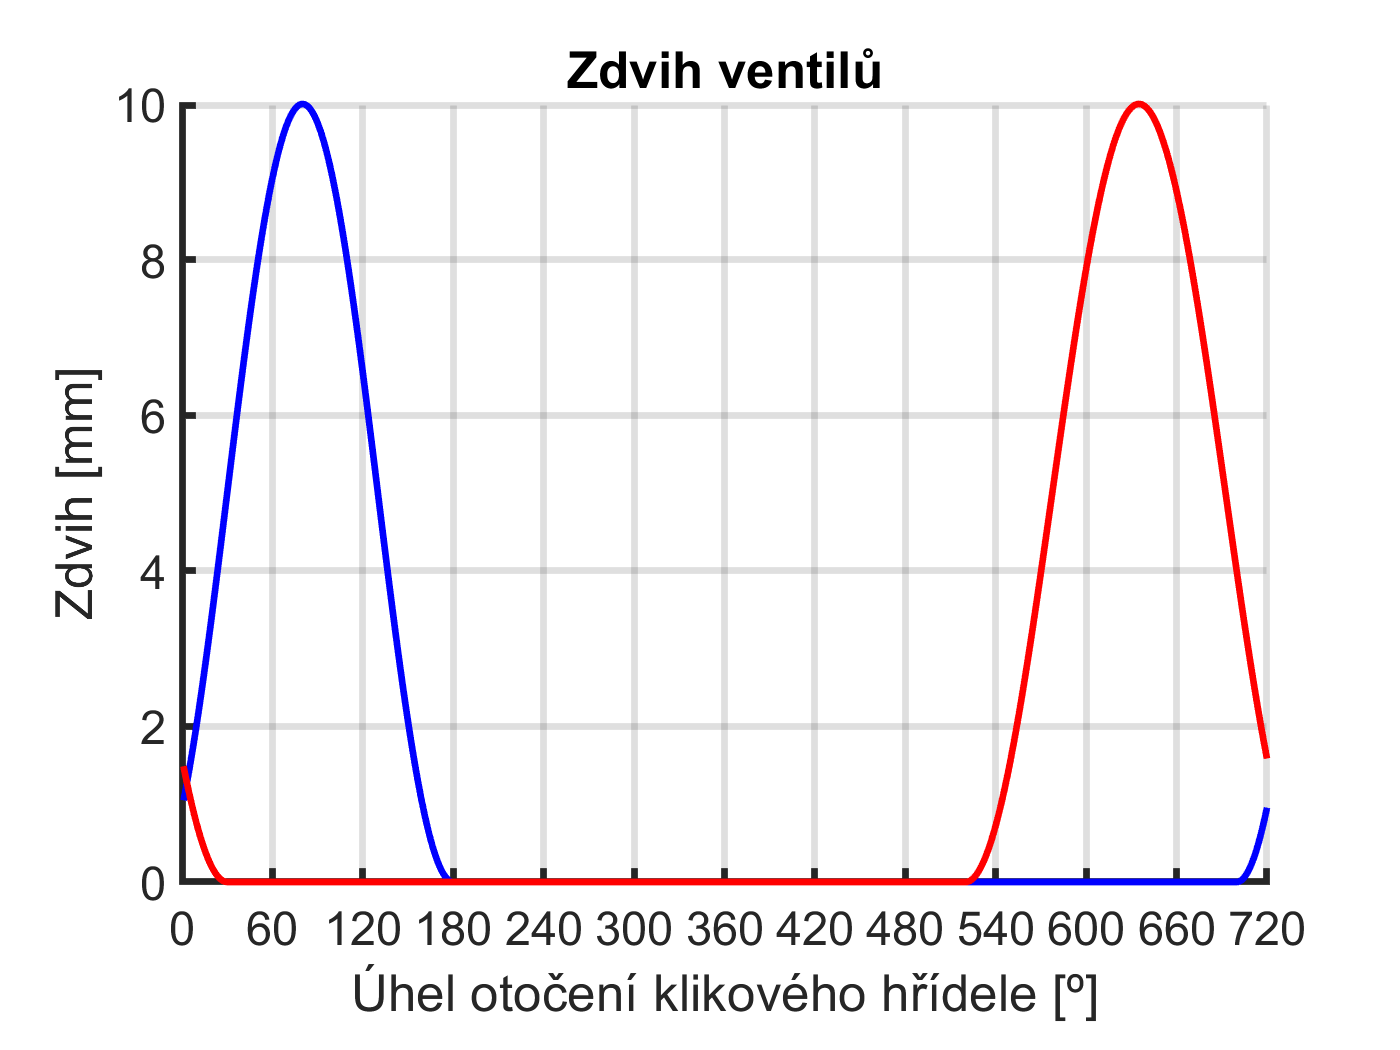

% Valve opening closing

th = linspace(1,720,720);

itho = 700;
ithc = 180;
iDp = 80;
ids = 8;
ilm = 10.0;

otho = 520;
othc = 30;
oDp = 60;
ods = 8;
olm = 10.0;


for fi=1:720

[iAA(fi), iLL(fi)] = valve(th(fi),itho,ithc,iDp,ids,ilm);
[oAA(fi), oLL(fi)] = valve(th(fi),otho,othc,oDp,ods,olm);
end

figure; 
ax1 = nexttile;

ax1.XTick = 0:60:720;
axis([ax1],[0 720 0 ilm]) 

title('Zdvih ventilů') 
xlabel('Úhel otočení klikového hřídele [º]') 
ylabel('Zdvih [mm]') 

set(gca, 'fontsize', 14,'linewidth',2);
hold on;
plot(th, iLL,'-b','linewidth',2);
plot(th, oLL,'-r','linewidth',2);
hold off;
grid on;

function [A,lift] = valve(th,tho,thc,Dp,ds,lm)

if (th > thc) && (th < tho) 
     A = 0;
    lift = 0;
    return;
end


if tho >= thc
  if th <= thc 
    th = th + 720.0;
  end
 thc = thc + 720.0;   
end

Ap = 0.35 * 0.25 * pi * (Dp^2 - ds^2);
lift = 0.5 * lm * (1 - cos(2*pi*(th-tho)/(thc-tho)));
Av = 0.35 * pi * Dp * lift;
if Av < Ap
    A = Av;
else
    A = Ap;
end
end